# **Project 4: The Gauntlet Challenge**

**By Adiella Chapa and Laurel Cox**

## Introduction

Our goal for this project is to get our Neato through the obstacle course of spiky walls and death traps so that it could touch the Ball of Benevolence, gaining the power of infinite knowledge. 

## Summary

To solve this challenge, we used gradient descent and implemented sinks and sources into our obtained (through LIDAR scans) map. The first thing we did was collect various scans of the gauntlet map by using a Neato. Once we got clean data of the walls and BoB, we obtained the x and y coordinates of the BoB to create our sink. We augmented our sink so that it would be prominent on our contour and surf graph, and we used  the following equation to do so:


$$38*\log \left(\sqrt{\left.{\left(x-0\ldotp 244\right)}^2 +{\left(y-1\ldotp 128\right)}^2 \right)}\right)$$
 

where 38 magnifies the sink and 0.244,1.128 are the x and y coordinates of a point of our sink, respectively. 

Additionally, we used the points we obtained for our scans to account for the walls (sources). We also magnified the sources to make sure they were visible. We used the following equation to do this: 


$$v-0\ldotp 16*\log \left(\sqrt{{\left(x-x\_\textrm{coord}\right)}^2 +{\left(y-y\_\textrm{coord}\right)}^2 }\right)$$


Where v represents the sink, 0.16 represents how much we scaled our sources by, and x_coord and y_coord represent the points we obtained through our LIDAR scan.

We made sure that the sinks and sources were being accounted for by creating a contour plot. After getting our correct contour plot,we obtained the gradient of our gauntlet map. We used the following equation to obtain our gradient:


$$100*\log \left(\sqrt{{\left(x-0\ldotp 244\right)}^2 +{\left(y-1\ldotp 128\right)}^2 }\right)$$


This one using the scalar 100 for a more dramtic sink. We found the derivatives of this function when plugging in our x values and y values; thus, obtaining our gradient. 

We also used the following gradient descent equation to when programming the Neato:


$$r-\lambda *\textrm{gradient}$$


where r is the input and $\lambda$ is the step size.

## Code Starts Here:

## Generating Gauntlet Map

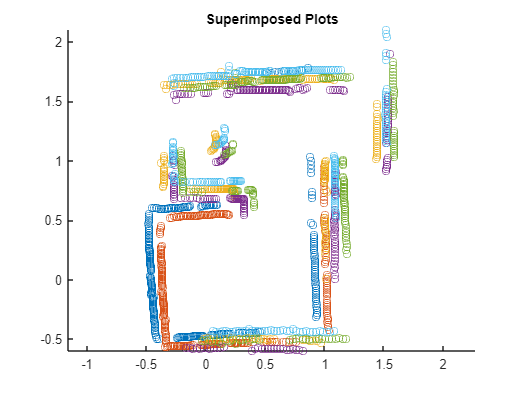

buildMap()

## Creating Potential Field

neatov2.connect()

Deleting previous Neato connection.
Connecting to the Neato.


ans =   neatov2 with no properties.


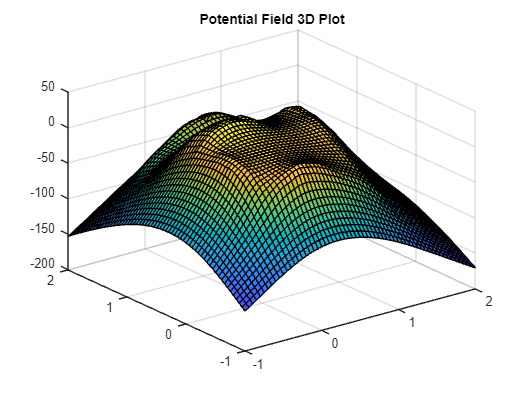

load("global_points.mat")
[v, x, y] = functionFromPoints(global_points);

figure();
surf(x, y, v)
title('Potential Field 3D Plot')

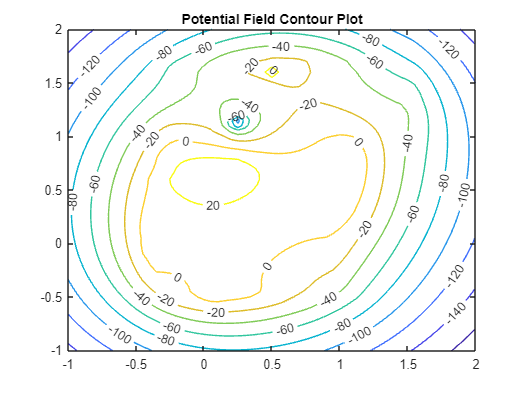

figure();
contour(x,y,v,'ShowText','On')
title('Potential Field Contour Plot')

neatov2.setFlatlandContours(x,y,v);

## Vector Field

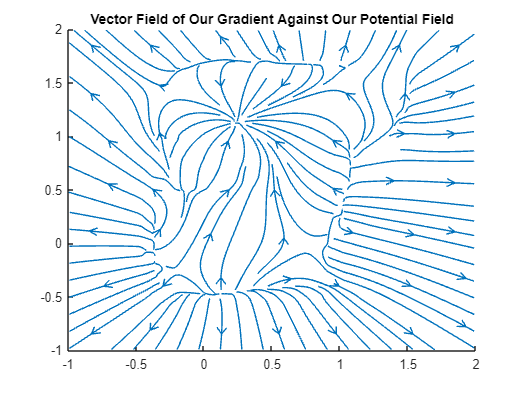

syms x y

[a, b] = meshgrid(-1:0.05:2, -1:0.05:2);
% flatlands
f = 100 * log(sqrt((x - 0.244).^2 + (y - 1.128).^2));

% Iterate through all global points
for i = 1:length(global_points)
    % Extract x, y coordinate pair
    x_coord = global_points(1, i);
    y_coord = global_points(2, i);

    % Add contribution from the current global point
    f = buildEquation(f, x, y, x_coord, y_coord);
end

% Compute the gradient components symbolically
df_dx = diff(f, x);
df_dy = diff(f, y);

% Convert symbolic expressions to functions
gradient_f_x = matlabFunction(df_dx, 'Vars', {x, y});
gradient_f_y = matlabFunction(df_dy, 'Vars', {x, y});

% Evaluate the functions at specific points
fxn = gradient_f_x(a, b);
fyn = gradient_f_y(a, b);

figure();
streamslice(a, b, -fxn, -fyn); hold on
title("Vector Field of Our Gradient Against Our Potential Field");

## Implementing Descent With Neato

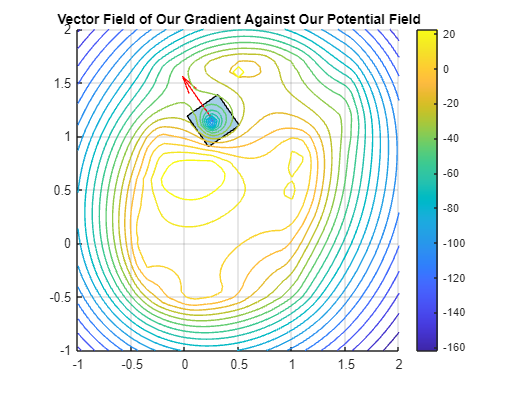

syms x y

% flatlands
f = 100*log(sqrt((x-0.244).^2+(y-1.128).^2));

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    f = buildEquation(f, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

fx = diff(f,x);
fy = diff(f,y);
gradient = [fx, fy];

%Starting position and orientation
startingx = 0;
startingy = 0;
startingTheta = 0;

%Parameters
%lambda = 0.0000000005;
linearWheelV = 0.1/3;

%While loop parameters
i = 2;
i_max = 26; %had at 19 for vid

%Initial position and gradient
r_0 = [startingx; startingy]; %First coordinate
r_list(:,1) = r_0;
r = r_0;

grad = double(subs(gradient, {x, y}, {r(1), r(2)}));
% neatov2.setPositionAndOrientation(startingx,startingy,startingTheta) %simulator

orientation = startingTheta;

while i < i_max && norm(grad) > 0.5
    grad = (double(subs(gradient, {x, y}, {r(1), r(2)})))';
    % CHANGE FOR #6: make lambda proportional to the gradiant
    norm(grad);
    lambda = 0.00004*norm(grad); % default lambda
    if norm(grad) > 190 % adjust lambda for extra steep steps
        lambda = 0.0000005*norm(grad); 
            if norm(grad) > 500 % adjust lambda for extra steep steps
                lambda = 0.00000005*norm(grad);
                if norm(grad) > 500 % adjust lambda for extra steep steps
                    lambda = 0.000000025*norm(grad); 
                end
            end
    end
    next_r = r - lambda*grad;
    vectorDiff = -lambda*grad;
    newOrientation = atan2(vectorDiff(2),vectorDiff(1));

    
    deltaTheta = newOrientation-orientation;
    angularS= 0.1;
    angularV = (0.1/0.254)*angularS;
    spinTime = abs(deltaTheta/angularV);
    neatov2.driveFor(spinTime, sign(deltaTheta)*angularS*-0.05, sign(deltaTheta)*angularS*0.05, true); %true for sim
    pause(.01)

    distance = norm(vectorDiff);
    % CHANGE FOR #6: if distance of path is insignificant, end the loop
    if distance < 0.0025
        break
    end
    driveTime = distance/linearWheelV;
    neatov2.driveFor(driveTime, linearWheelV, linearWheelV, true)  %true for sim 

    %%FOR NON-SIMULATED%%
    % pause(.01)

    r = next_r;
    r_list(:,i) = r(:,1);
    i = i + 1;

    orientation = newOrientation; 
end

## Experimental Evidence

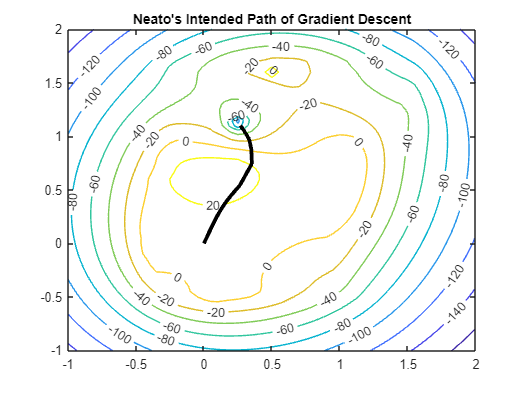

figure();
contour(a,b,v,'ShowText','On'); hold on
plot(r_list(1,:),r_list(2,:),'k', LineWidth=3)
title("Neato's Intended Path of Gradient Descent")

This graph shows the intended path of the Neato when we incoporated gradient descent into the Neato drive function.

## Link To Video

[https://youtube.com/shorts/mUf8cJCh3jI?feature=share](https://youtube.com/shorts/mUf8cJCh3jI?feature=share) 